# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 6;

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp6'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.5459   -0.5650   -0.5555   -0.5315   -0.5602   -0.6225   -0.5363   -0.5363   -0.6129   -0.5602   -0.5555   -0.6369   -0.5219   -0.5986   -0.5507   -0.5794   -0.5602   -0.5698   -0.5315   -0.6129   -0.5602   -0.5746   -0.5650   -0.6081   -0.6129   -0.5555   -0.5842   -0.6800   -0.5746   -0.6512   -0.5986   -0.6081   -0.5555   -0.5411   -0.6321   -0.5315   -0.6273   -0.5746   -0.5459   -0.5890   -0.5698   -0.5028   -0.5602   -0.5555   -0.5746   -0.5698   -0.6273   -0.5698   -0.6081   -0.5794
   -0.1772   -0.1772   -0.2251   -0.1963   -0.1628   -0.1724   -0.1580   -0.1389   -0.1245   -0.2059   -0.1245   -0.1484   -0.2059   -0.2059   -0.1820   -0.1628   -0.1963   -0.1580   -0.1628   -0.1293   -0.2155   -0.1867   -0.1628   -0.1006   -0.2442   -0.1628   -0.1484   -0.2203   -0.2442   -0.1915   -0.1963   -0.1915   -0.1724   -0.1963   -0.1867   -0.1101   -0.2538   -0.1484   -0.1820   -0.1580   -0.2203   -0.1676   -0.1963   -0.1006   -0.2059   -0.1724   -0.1963   -0.1820   -0.1628   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

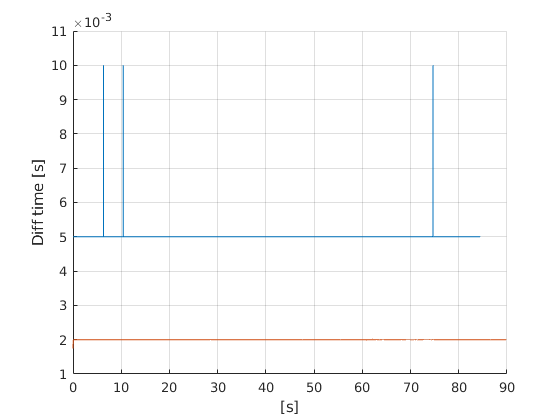

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

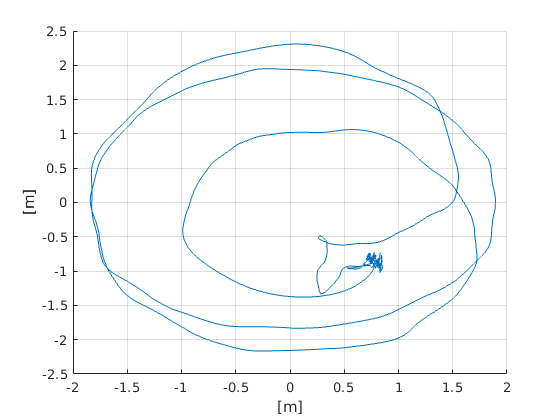

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

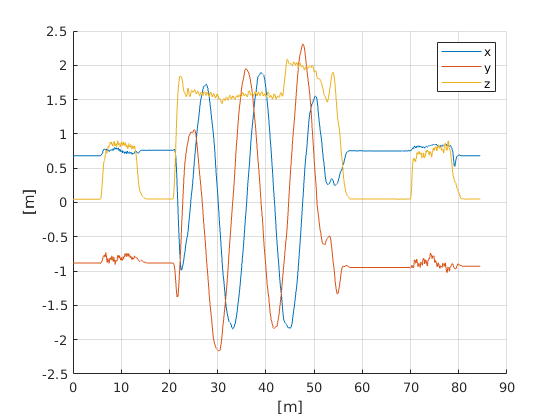

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

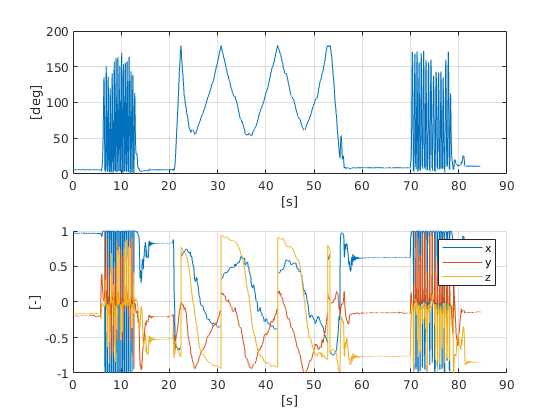

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN   -0.0228    0.0719    0.0478    0.0090   -0.0671   -0.0917   -0.0259   -0.0096    0.0097    0.0406   -0.0301   -0.0169    0.0199   -0.0184   -0.0302    0.0334    0.0269   -0.0036   -0.0059    0.0319    0.0460    0.0101   -0.0045   -0.0227   -0.0237    0.0538    0.0501   -0.0450   -0.0794   -0.0229    0.0675    0.0149    0.0131    0.0391    0.0106   -0.0275   -0.0363    0.0119    0.0156   -0.0181    0.0071    0.0250   -0.0810   -0.0046    0.0310    0.0230   -0.0094   -0.0667    0.0003
       NaN    0.0115    0.0122   -0.0312   -0.0072    0.0302    0.0450   -0.0176   -0.0236    0.0345    0.0326   -0.0078   -0.0171    0.0013    0.0057    0.0052   -0.0069   -0.0002    0.0067    0.0049    0.0135   -0.0136   -0.0168    0.0053    0.0154    0.0022   -0.0167    0.0071    0.0196   -0.0182   -0.0126    0.0121    0.0075    0.0055    0.0016   -0.0213    0.0016    0.0111   -0.0193    0.0127    0.0070   -0.0046   -0.0064    0.0053    0.0149   -0.0153   -0.0007    0.0075   -0.00

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

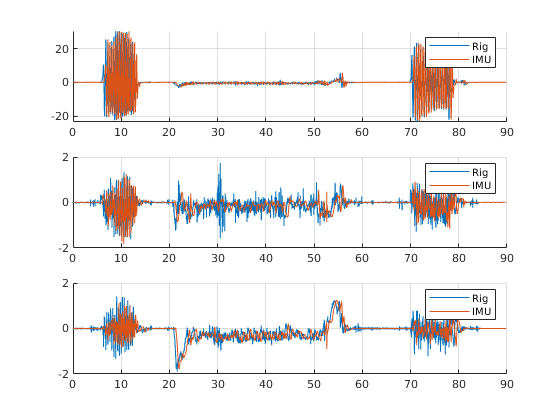

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

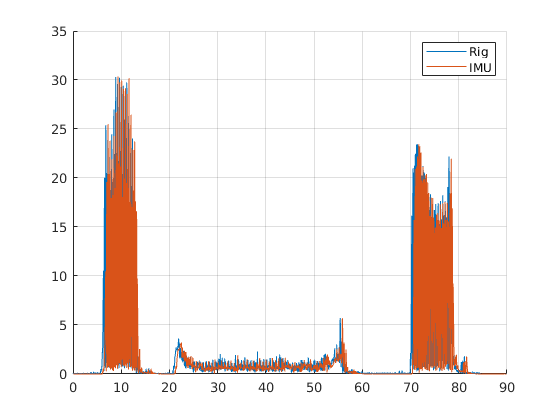

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0192    0.0195    0.0191    0.0193    0.0194    0.0194    0.0191    0.0189    0.0193    0.0192    0.0189    0.0188    0.0190    0.0190    0.0190    0.0190    0.0189    0.0190    0.0189    0.0190    0.0189    0.0188    0.0190    0.0190    0.0189    0.0188    0.0189    0.0190    0.0188    0.0188    0.0191    0.0189    0.0189    0.0188    0.0189    0.0188    0.0191    0.0188    0.0190    0.0190    0.0188    0.0189    0.0189    0.0190    0.0189    0.0188    0.0190    0.0189    0.0189    0.0189
    0.0987    0.0979    0.0984    0.0986    0.0989    0.0987    0.0982    0.0978    0.0980    0.0977    0.0981    0.0981    0.0978    0.0980    0.0980    0.0978    0.0977    0.0981    0.0979    0.0981    0.0979    0.0984    0.0983    0.0985    0.0983    0.0983    0.0981    0.0988    0.0986    0.0984    0.0978    0.0981    0.0984    0.0983    0.0986    0.0987    0.0987    0.0984    0.0983    0.0985    0.0985    0.0983    0.0985    0.0986    0.0977    0.0985    0.0980    0.0988    

for i = 1:3

imu_unit_tot =     0.0023    0.0032    0.0030    0.0024    0.0027    0.0020    0.0026    0.0028    0.0035    0.0032    0.0028    0.0017    0.0024    0.0013    0.0027    0.0036    0.0026    0.0030    0.0021    0.0021    0.0023    0.0020    0.0018    0.0030    0.0022    0.0023    0.0028    0.0016    0.0022    0.0023    0.0024    0.0023    0.0031    0.0028    0.0017    0.0016    0.0047    0.0015    0.0030    0.0034    0.0018    0.0034    0.0030    0.0023    0.0034    0.0021    0.0020    0.0013    0.0016    0.0032
    0.0533    0.0531    0.0523    0.0535    0.0531    0.0539    0.0531    0.0543    0.0537    0.0543    0.0541    0.0535    0.0531    0.0539    0.0535    0.0538    0.0535    0.0539    0.0540    0.0543    0.0530    0.0532    0.0542    0.0541    0.0535    0.0530    0.0542    0.0548    0.0538    0.0545    0.0544    0.0541    0.0532    0.0542    0.0550    0.0539    0.0543    0.0551    0.0544    0.0548    0.0537    0.0548    0.0540    0.0543    0.0528    0.0534    0.0540    0.0539    

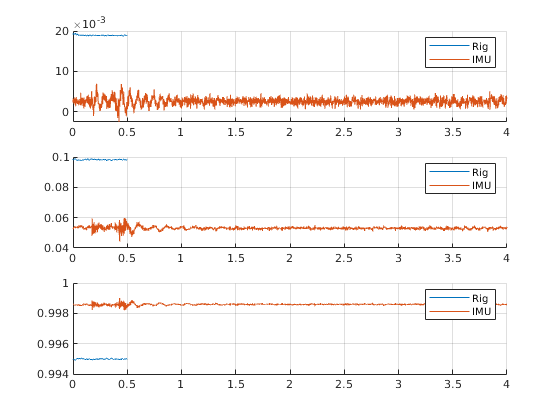

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 5.820e-04 / 1.000e-12
2/100: tol: 4.398e-12 / 1.000e-12
3/100: tol: 8.652e-18 / 1.000e-12


R_stationary_rig_mean =     0.9997   -0.0175    0.0189
    0.0155    0.9950    0.0982
   -0.0206   -0.0979    0.9950


e_R = 	1.0e+-3 *

   -0.4311    0.2992   -0.2069   -0.4237   -0.6827   -0.5143   -0.0186    0.3969    0.2471    0.4983    0.1427    0.0786    0.4454    0.2525    0.2464    0.4385    0.5485    0.1036    0.2805    0.1396    0.3373   -0.1852   -0.1242   -0.2822   -0.0807   -0.0581    0.1587   -0.5959   -0.3478   -0.1481    0.4538    0.0831   -0.2263   -0.0682   -0.3584   -0.4586   -0.4597   -0.1828   -0.1001   -0.2976   -0.2571   -0.1171   -0.3270   -0.3678    0.4861   -0.3270    0.1754   -0.5547    0.2677    0.1136
    0.2744    0.5067    0.1468    0.3875    0.4512    0.4530    0.1306   -0.0023    0.3213    0.2412   -0.0301   -0.1176    0.0447    0.0619    0.0341    0.0174   -0.0196    0.0815   -0.0076    0.0198   -0.0636   -0.1257    0.0634    0.0504    0.0090   -0.1106   -0.0032    0.0514   -0.0873   -0.1465    0.1033   -0.0237   -0.0191   -0.1006   -0.0727   -0.1051    0.1453   -0.1210    0.0219    0.0808   -0.0951    0.0108   -0.0454    0.0711   -0.0925   -0.0907    0.0499   -0.0719 

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0189
    0.0982
    0.9950


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =     0.0025
    0.0531
    0.9986



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.7603

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9999    0.0004    0.0164
   -0.0011    0.9990    0.0453
   -0.0164   -0.0453    0.9988


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.5953
    0.9393
   -0.0647



det(R_rig_coarse2rig_fine)

ans = 1

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0189
    0.0982
    0.9950


dir_rig

dir_rig =     0.0189
    0.0982
    0.9950


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 1.2319e-09

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.7603

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0187    0.0197    0.0194    0.0188    0.0191    0.0184    0.0190    0.0192    0.0199    0.0196    0.0192    0.0181    0.0188    0.0177    0.0192    0.0201    0.0190    0.0195    0.0185    0.0185    0.0187    0.0184    0.0183    0.0194    0.0186    0.0187    0.0192    0.0180    0.0187    0.0188    0.0188    0.0187    0.0195    0.0193    0.0181    0.0181    0.0211    0.0179    0.0194    0.0198    0.0183    0.0199    0.0194    0.0187    0.0199    0.0185    0.0185    0.0177    0.0181    0.0197
    0.0985    0.0982    0.0975    0.0986    0.0983    0.0991    0.0983    0.0995    0.0989    0.0994    0.0992    0.0986    0.0982    0.0991    0.0987    0.0990    0.0986    0.0990    0.0991    0.0995    0.0982    0.0983    0.0993    0.0992    0.0986    0.0982    0.0993    0.1000    0.0990    0.0997    0.0995    0.0992    0.0983    0.0993    0.1002    0.0991    0.0994    0.1002    0.0995    0.0999    0.0989    0.0999    0.0991    0.0994    0.0979    0.0986    0.0991    0.0990  

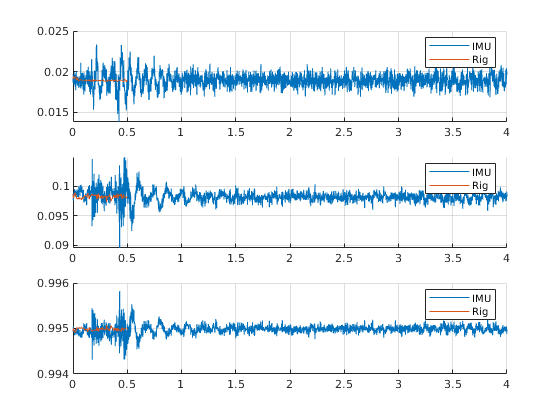

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

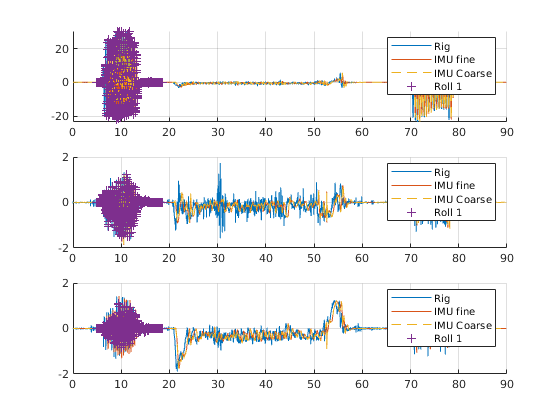

phase_roll_1 = data_IMU.start_and_stop(2,1):data_IMU.start_and_stop(3,1);
gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

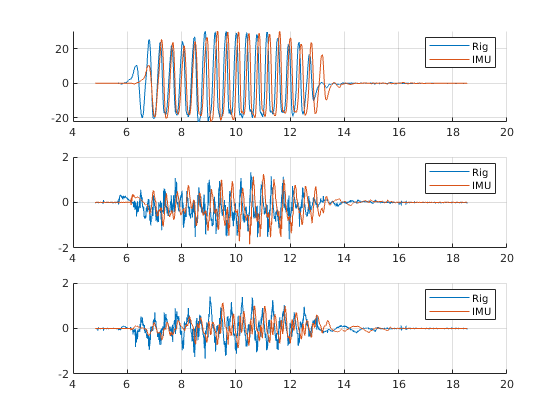


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =         2413        2414        2415        2416        2417        2418        2419        2420        2421        2422        2423        2424        2425        2426        2427        2428        2429        2430        2431        2432        2433        2434        2435        2436        2437        2438        2439        2440        2441        2442        2443        2444        2445        2446        2447        2448        2449        2450        2451        2452        2453        2454        2455        2456        2457        2458        2459        2460        2461        2462


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 6858

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 0.5


ans =    -0.0194   -0.0148    0.0312    0.0687    0.0558    0.0236   -0.0014   -0.0231   -0.0353   -0.0168    0.0205    0.0296    0.0165    0.0025   -0.0049   -0.0104   -0.0097    0.0066    0.0199    0.0078   -0.0168   -0.0234   -0.0199   -0.0133    0.0174    0.0689    0.0811    0.0615    0.0336    0.0007   -0.0370   -0.0594   -0.0743   -0.0816   -0.0672   -0.0332   -0.0079    0.0130    0.0245    0.0235    0.0212    0.0206    0.0218    0.0240    0.0331    0.0481    0.0502    0.0310    0.0076   -0.0114


grid_search = t_shift_coarse + (-0.3:0.01:0.3);
cost_grid = arrayfun(cost, grid_search);


ans = 1.0808e+06

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 0.5000

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1        0.42918       253909        initial
    2        0.57082  2.20699e+06        golden
    3       0.341641  2.40496e+06        golden
    4       0.458811      708.339        parabolic
    5       0.465423      7881.76        parabolic
    6       0.460075      214.718        parabolic
    7       0.460151      213.166        parabolic
    8        0.46015      213.166        parabolic
    9        0.46015      213.166        parabolic
   10        0.46015      213.166        parabolic
   11        0.46015      213.166        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

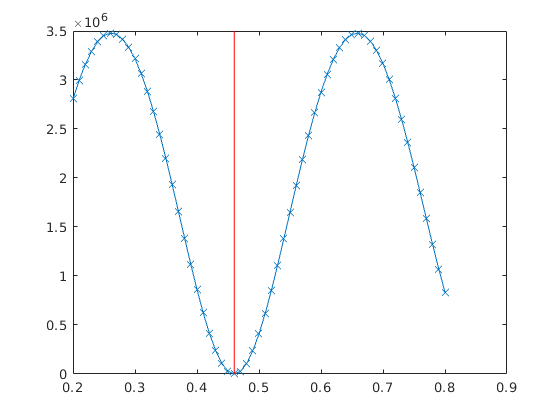

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


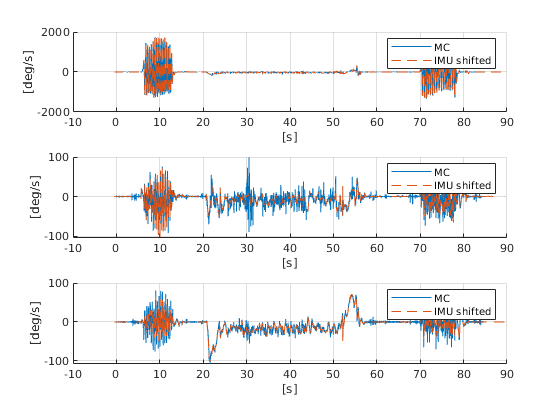

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time, "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
ylim([-1.35 0.71])

## Find release times

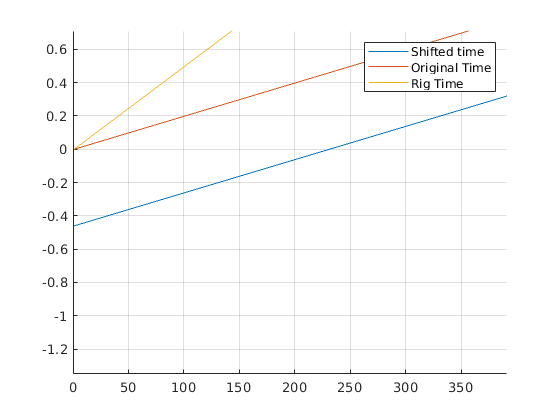



release_times_roll_2 = 70 + (0:19)*0.2
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 21 + (0:19)*1.6
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';

release_times_roll_2 =    70.0000   70.2000   70.4000   70.6000   70.8000   71.0000   71.2000   71.4000   71.6000   71.8000   72.0000   72.2000   72.4000   72.6000   72.8000   73.0000   73.2000   73.4000   73.6000   73.8000


w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;

release_times_middle =    21.0000   22.6000   24.2000   25.8000   27.4000   29.0000   30.6000   32.2000   33.8000   35.4000   37.0000   38.6000   40.2000   41.8000   43.4000   45.0000   46.6000   48.2000   49.8000   51.4000


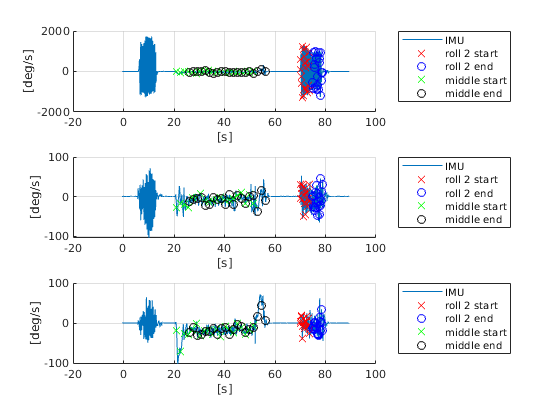


    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

mkdir(fullfile(pathScript,"estimated_parameters"))

% save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt");
save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");
% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 